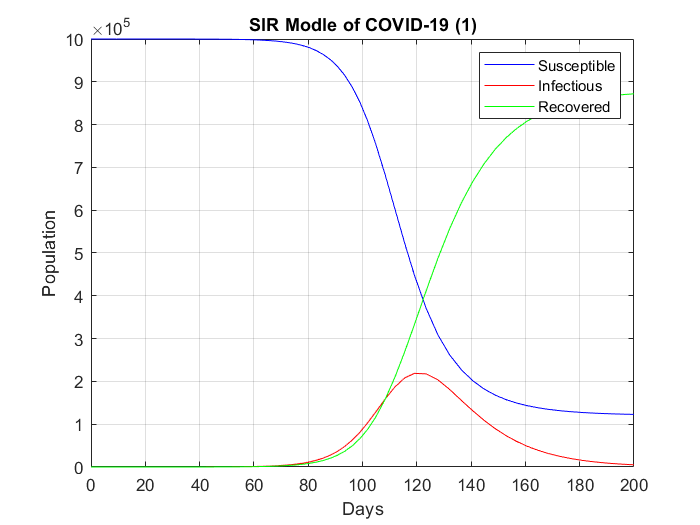

%(1) Simulated Model of given parameters
%Assign a value to each parameter
beta=0.2;
gama=0.083;
N=1000000;
ts=[0 200];
y0=[999999 1 0];
%Return the data from the simulated model
[t,y]=ode45(@(t,y)SIR(t,y,beta,gama,N),ts,y0);
%Plot including the number of 'Susceptible','Infectious','Recovered'
plot(t,y(:,1),'b',t,y(:,2),'r',t,y(:,3),'g');
xlabel('Days');
ylabel('Population');
legend('Susceptible','Infectious','Recovered');
title('SIR Modle of COVID-19 (1)');
grid on;

output = struct with fields:
    iterations: 501
     funcCount: 982
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 ↵'


The model was found successfully.


modCase = 	1.0e+05 *

    0.0000
    0.0003
    0.0007
    0.0012
    0.0018
    0.0027
    0.0037
    0.0050
    0.0066
    0.0087


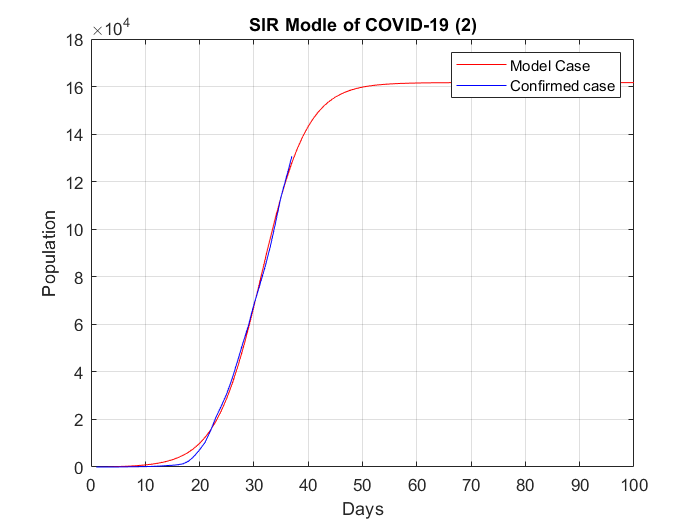


%(2) Real Model on real data
%Find the optimized parameters 'S0','β'and'γ'
b0=[24.9583,26.8431,9999999];
options=optimset('MaxFunEvals',2e40,'MaxIter',2e40);
[b,fmin,exitflag,output]=fminsearch(@SIR2,b0,options);
if exitflag==1
%Found the model
%Output the interations,etc
%Plot the result
output
disp("The model was found successfully.")
beta=b(1);
gama=b(2);
N=8540000;
ts=1:1:100;
y0=[b(3) 1 0];
[t,y]=ode45(@(t,y)SIR(t,y,beta,gama,N),ts,y0);
modCase=y(:,2)+y(:,3)
%Plot including the number of 'Model Case'and'Confirmed case'
plot(t,modCase,'r');
hold on;
Ca=numGet();
t=1:1:37;
plot(t,Ca,'b');
xlabel('Days');
ylabel('Population');
legend('Model Case','Confirmed case');
title('SIR Modle of COVID-19 (2)');
grid on;
else
disp("No accurate model was found.")
end